# Homework 3

**Name:** YOUR NAME HERE

**Due Date: **

clear, clc

## Problem #1 - Numerical integration methods 

**SETUP FOR PROBLEM**

f = @(x) 4*x.^5 -5.9*x.^4 - 3.1*x.^3 - x.^2 + 5*x + 14;
a = 0;
b = 2;

**a) Exact integral**

g = @(x) 4/6*x.^6 - 5.9/5*x.^5 - 3.1/4*x.^4 - 1/3*x.^3 + 5/2*x.^2 + 14*x;
I_true = g(b) - g(a)

I_true = 27.8400

**b) Trapezoid - Single application**

I_trap_n1 = (b-a)*((f(a)+f(b))/2)

I_trap_n1 = 42.8000

**c) Trapezoid Rule - Composite application (n=7)**

n = 7;
h = (b-a)/n;
I_trap_n7 = (h/2)*(f(a) + 2*f(a+h) + 2*f(a+2*h) + 2*f(a+3*h) + 2*f(b-3*h) + 2*f(b-2*h) + 2*f(b-h) + f(b))

I_trap_n7 = 28.4460

**d) Simpson's 1/3 Rule - Single application**

n = 2;
h = (b-a)/n;
I_simp1_n1 = h/3*(f(a)+4*f(a+h)+f(b))

I_simp1_n1 = 31.6000

**e) Simpson's 3/8 Rule - Single application**

n = 3;
h = (b-a)/n;
I_Simp3_n1 = (3*h)/8*(f(a) + 3*f(a+h) + 3*f(b-h) + f(b))

I_Simp3_n1 = 29.5111

**f) Hybrid Simpson's (n=7)**

[I_Simp_hyb1, I_Simp_hyb2, I_Simp_hyb3] = simpsons7(f,a,b)

I_Simp_hyb1 = 27.8894

I_Simp_hyb2 = 27.8676

I_Simp_hyb3 = 27.8785

**g) Table with integral results**

MTPRE = @(estimate) abs((I_true - estimate)/I_true)*100

MTPRE = function_handle with value:
    @(estimate)abs((I_true-estimate)/I_true)*100

Index = ["Exact", "TrapSingle", "Simpsons 1/3", "Simpsons 3/8", "TrapComposite", "s13 - s13 - s38", "s38 - s13 - s13", "s13 - s38 - s13"];
Value = [I_true, I_trap_n1, I_simp1_n1, I_Simp3_n1, I_trap_n7, I_Simp_hyb1, I_Simp_hyb2, I_Simp_hyb3];

for i = 1:length(Index)
    if i == 1
        fprintf("Method          Value     MTPRE   \n" + ...
        "--------------- --------- --------\n")
    end
    fprintf("%-15s %9.4f %8.4f\n", Index(i), Value(i), MTPRE(Value(i)))
end

Method          Value     MTPRE   
--------------- --------- --------


Exact             27.8400   0.0000
TrapSingle        42.8000  53.7356
Simpsons 1/3      31.6000  13.5057
Simpsons 3/8      29.5111   6.0026
TrapComposite     28.4460   2.1767
s13 - s13 - s38   27.8894   0.1773
s38 - s13 - s13   27.8676   0.0991
s13 - s38 - s13   27.8785   0.1382


## Problem #2 - Integrating real data

**SETUP FOR PROBLEM**

data = [0, .25, .42, .66, .92, 1.19, 1.38, 1.63, 1.72, 2;
        -5.29, -2.61, -.45, 4.71, 5.76, 27.99, 36.55, 58.28, 68.38, 89.1];

**a) Plot the data**

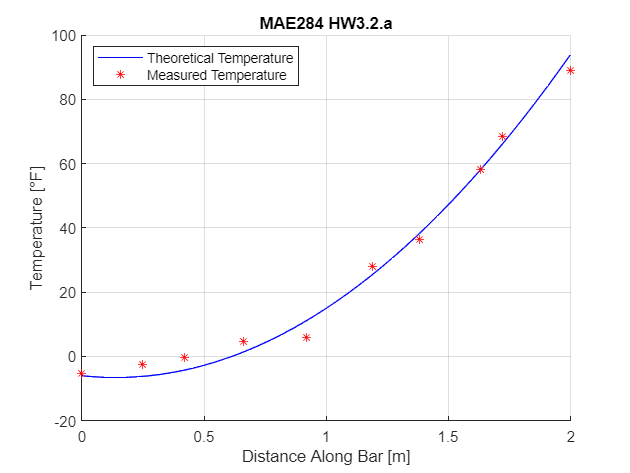

temp = @(x) 29*x.^2 - 8*x - 6;
figure()
hold on
fplot(temp, [0,2], "b-")
plot(data(1,:), data(2,:), "r*")
xlim([0,2])
grid on
legend("Theoretical Temperature", "Measured Temperature", "location", "northwest")
xlabel("Distance Along Bar [m]")
ylabel("Temperature [°F]")
title("MAE284 HW3.2.a")
hold off

**b) Estimate the integral of the data**

IntTrap = [];
for i = 1:(length(data(1,:))-1)
    IntTrap(i) = (data(1,i+1)-data(1,i))*((data(2,i)+data(2,i+1))/2);
end
EstInt = sum(IntTrap);
fprintf("The extimated value of the integral of the data using the trapezoid method is %.4f", EstInt)

The extimated value of the integral of the data using the trapezoid method is 50.9129

**c) Magnitude true percent relative error**

TrueInt = integral(temp,0,2);
MTPRE = abs((TrueInt-EstInt)/TrueInt)*100;
fprintf("The magnitude of true percent relative error is %.2f %%", MTPRE)

The magnitude of true percent relative error is 3.20 %

## Problem #3 - 2D Integration

**SETUP FOR PROBLEM**

f = @(x,y) 160+ (x.^2/9 + y.^2/16)

f = function_handle with value:
    @(x,y)160+(x.^2/9+y.^2/16)


a = -15;
b = -14.5;
c = -16;
d = 4;

x = linspace(a,b);
y = linspace(c,d);

[X,Y] = meshgrid(x,y);
Z = f(X,Y);

**a) 3D plot of function**

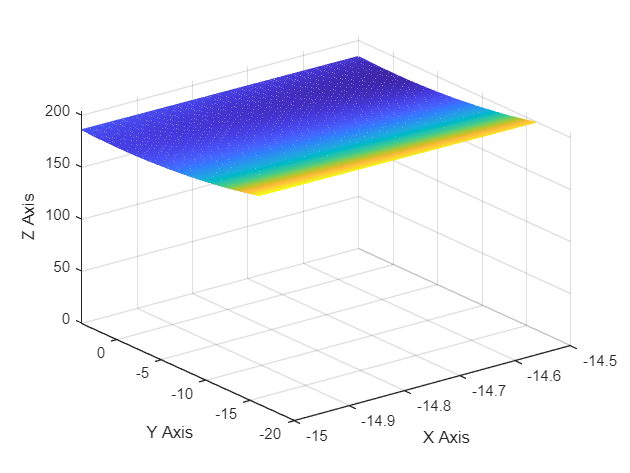

figure()
mesh(X, Y, Z)
xlabel("X Axis")
ylabel("Y Axis")
zlabel("Z Axis")
v = axis;
zlim([0,v(6)])

**b) Integral estimate using Simpson's 3/8: Start with x axis**

n = 3;
h = (b-a)/n;
Simp38x = h/2*(f(a,c) + 3*f(a+h,c) + 3*f(b-h,c) + f(b,c)) * abs(d-c);
fprintf("The Estimated value of the integral starting at the x-axis is %.4f", Simp38x)

The Estimated value of the integral starting at the x-axis is 2669.0123

**c) Integral estimate using Simpson's 3/8: Start with y axis**

n = 3;
h = (d-c)/n;
Simp38y = h/2*(f(c,a) + 3*f(c+h,a) + 3*f(d-h,a) + f(d,a)) * abs(b-a);
fprintf("The Estimated value of the integral starting at the y-axis is %.4f", Simp38y)

The Estimated value of the integral starting at the y-axis is 2423.5494

**d) True value of the integral**

% syms x
% int()

**e) Are the results from b through d the same? Why or why not?**

No, by using a single application of Simpson's 3/8 we have far less accuracy than the int function of the symbolic math toolbox, as it uses one rough estimate, comapred to many smaller segments

**f) Extra Credit (10 points) Plot a plane and extra points in a new figure**

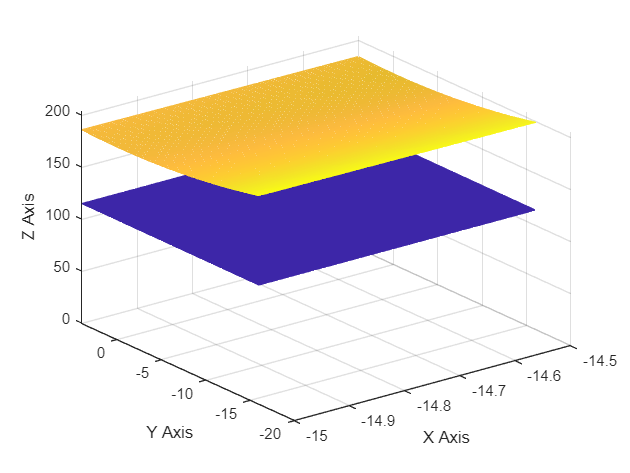

figure()
mesh(X,Y,Z)
hold on
xlabel("X Axis")
ylabel("Y Axis")
zlabel("Z Axis")
v = axis;
zlim([0,v(6)])
z115 = linspace(115,115);
for i = 1:100
    z115(i,:) = z115(1);
end

mesh(X,Y,z115, "FaceColor","flat")

## Problem #4 - Gauss-Legendre

**SETUP FOR PROBLEM**

**a) Plot the function. Include a solid black line on the x axis. **

**b) Exact value of the integral**

**c) 3 Point Gauss-Legendre**

**d) Why is the true error nonzero for the Gauss-Legendre method?**

EXPLAIN HERE

Because of the different order approx, trying to estimate a 6th order, and we are using a method with xero error for a 5th order

## Problem #5 - Romberg Integration

**SETUP FOR PROBLEM**

f = @(x) 4*x.^5 -5.9*x.^4 - 3.1*x.^3 - x.^2 + 5*x + 14;
a = 0;
b = 2;

**a) Romberg by hand**

I11 = trap(f,a,b,1);
I12 = trap(f,a,b,2);
I13 = trap(f,a,b,4);
I14 = trap(f,a,b,8);
I21 = 4/3*I12 - 1/3*I11;
I22 = 4/3*I13 - 1/3*I12;
I23 = 4/3*I14 - 1/3*I13;
I31 = 16/15*I22- 1/15*I21;
I32 = 16/15*I23 - 1/15*I22;
I41 = 64/63*I32 - 1/63*I31;

fprintf("j        k=1        k=2        k=3             k=4\n" + ...
        "- ---------- ---------- ---------- ---------------\n" + ...
        "1 %10.5f %10.5f %10.5f %15.10f\n" + ...
        "2 %10.5f %10.5f %10.5f\n" + ...
        "3 %10.5f %10.5f\n" + ...
        "4 %10.5f", I11, I12, I13, I14, I21, I22, I23, I31, I32, I41)

j        k=1        k=2        k=3             k=4
- ---------- ---------- ---------- ---------------
1   42.80000   34.40000   29.65625   28.3050781250
2   31.60000   28.07500   27.85469
3   27.84000   27.84000
4   27.84000

**b) Romberg function**

## Helper functions

### Hybrid simpsons's (n=7)

function [I1, I2, I3] = simpsons7(f,a,b)
% composite application of simpsons' 1/3 and 3/8 rules
%  
% Inputs:
% f = function to be called
% a,b = integration limits
% Outputs:
% I1 = 1/3, 1/3, 3/8
% I2 = 1/3, 3/8, 1/3
% I3 = 3/8, 1/3, 1/3
%
% Calls functions simpson13 and simpson38

% Created by Jackson Lee
% Feb 21, 2023

h = (b-a)/7;

I1 = simpson13(f,a,a+2*h,2) + simpson13(f,a+2*h,a+4*h,2) + simpson38(f,a+4*h,b,3);
I2 = simpson38(f,a,a+3*h,3) + simpson13(f,a+3*h,a+5*h,2) + simpson13(f,b-2*h,b,2);
I3 = simpson13(f,a,a+2*h,2) + simpson38(f,a+2*h,a+5*h,3) + simpson13(f,b-2*h,b,2);


end

### Trap function (from textbook)

function I = trap(func,a,b,n,varargin)
% trap: composite trapezoidal rule quadrature
% I = trap(function,a,b,n,p1,p2,...): 
%           composite trapezoidal rule
%
% Inputs:
% func = function to be integrated
% a,b = integration limits
% n = number of segments (default = 100)
% p1, p2,... = additional parameters used by func
% Output:
% integral estimate

%Created by: Isheeta Ranade
% Feb 08, 2017
% Updated on Feb 13, 2018

if nargin<3, error('At least 3 input arguments required'), end %Error check to ensure 3 inputs are included
if ~(b>a), error('Upper bound must be greater than lower'), end % Ensure that b is greater than a. If not exit the function
if nargin<4 || isempty(n), n = 100; end %Ensure n is specified. If not set to 100

x = a;
h = (b-a)/n; %Compute step size h
s = func(a,varargin{:});
for i = 1:n-1
    x = x+h; %Increment location of x
    s = s + 2*func(x,varargin{:}); %Include the summation of all interior segments into s
end
s = s + func(b,varargin{:}); %Add the last term to s
I = (b-a)*s/(2*n); %Compute the integral approximation using the summation term.
end

### Romberg function (from textbook)